% Load the necessary files
load('HCP_Contrast_FC_HCP_MMP.mat')
load('HCP_FC_HCP_MMP.mat')
load HCPex_LabelID.mat; % standard HCPex, 360 long. Huang, Rolls et al 2022 doi: 10.1007/s00429-021-02421-6
HCP_name = LabelID(:,4);
load('HCP_task_rest_covariates.mat')
load('labels_regions_2.mat')
HCP_L=HCP_name(1:180);
HCP_R=HCP_name(181:360);

% Prepare the task-related functional connectivty matrices 
% The matrices are to be stored in 360x360x100 matrcies
% or in 180x180x100 for single hemisphere data
Emotion_FC=cell2mat(HCP_FC(1).FC(:,2));
Emotion_FC=reshape(Emotion_FC,360,100,360);
Emotion_FC=permute(Emotion_FC,[1,3,2]);
Emotion_FC_L=Emotion_FC(1:180,1:180,:);
Emotion_FC_R=Emotion_FC(181:360,181:360,:);
Gambling_FC=cell2mat(HCP_FC(2).FC(:,2));
Gambling_FC=reshape(Gambling_FC,360,100,360);
Gambling_FC=permute(Gambling_FC,[1,3,2]);
Gambling_FC_L=Gambling_FC(1:180,1:180,:);
Gambling_FC_R=Gambling_FC(181:360,181:360,:);
Language_FC=cell2mat(HCP_FC(3).FC(:,2));
Language_FC=reshape(Language_FC,360,100,360);
Language_FC=permute(Language_FC,[1,3,2]);
Language_FC_L=Language_FC(1:180,1:180,:);
Language_FC_R=Language_FC(181:360,181:360,:);
Motor_FC=cell2mat(HCP_FC(4).FC(:,2));
Motor_FC=reshape(Motor_FC,360,100,360);
Motor_FC=permute(Motor_FC,[1,3,2]);
Motor_FC_L=Motor_FC(1:180,1:180,:);
Motor_FC_R=Motor_FC(181:360,181:360,:);
Relational_FC=cell2mat(HCP_FC(5).FC(:,2));
Relational_FC=reshape(Relational_FC,360,100,360);
Relational_FC=permute(Relational_FC,[1,3,2]);
Relational_FC_L=Relational_FC(1:180,1:180,:);
Relational_FC_R=Relational_FC(181:360,181:360,:);
Social_FC=cell2mat(HCP_FC(6).FC(:,2));
Social_FC=reshape(Social_FC,360,100,360);
Social_FC=permute(Social_FC,[1,3,2]);
Social_FC_L=Social_FC(1:180,1:180,:);
Social_FC_R=Social_FC(181:360,181:360,:);
WM_FC=cell2mat(HCP_FC(7).FC(:,2));
WM_FC=reshape(WM_FC,360,100,360);
WM_FC=permute(WM_FC,[1,3,2]);
WM_FC_L=WM_FC(1:180,1:180,:);
WM_FC_R=WM_FC(181:360,181:360,:);
Rest_FC=cell2mat(HCP_FC(8).FC(:,2));
Rest_FC=reshape(Rest_FC,360,100,360);
Rest_FC=permute(Rest_FC,[1,3,2]);
Rest_FC_L=Rest_FC(1:180,1:180,:);
Rest_FC_R=Rest_FC(181:360,181:360,:);

% Prepare the subtask-related functional connectivity matrices
% The matrices are to be stored in 360x360x100 matrcies
% or in 180x180x100 for single hemisphere data
Emotion_fear_FC=reshape([HCP_contrast_FC(1).FC.fear],360,360,100);
[Emotion_fear_FC_L,Emotion_fear_FC_R]=split_HS(Emotion_fear_FC);
Emotion_neut_FC=reshape([HCP_contrast_FC(1).FC.neut],360,360,100);
[Emotion_neut_FC_L,Emotion_neut_FC_R]=split_HS(Emotion_neut_FC);
Gambling_win_FC=reshape([HCP_contrast_FC(2).FC.win],360,360,100);
[Gambling_win_FC_L,Gambling_win_FC_R]=split_HS(Gambling_win_FC);
Gambling_loss_FC=reshape([HCP_contrast_FC(2).FC.loss],360,360,100);
[Gambling_loss_FC_L,Gambling_loss_FC_R]=split_HS(Gambling_loss_FC);
Language_math_FC=reshape([HCP_contrast_FC(3).FC.math],360,360,100);
[Language_math_FC_L,Language_math_FC_R]=split_HS(Language_math_FC);
Language_story_FC=reshape([HCP_contrast_FC(3).FC.story],360,360,100);
[Language_story_FC_L,Language_story_FC_R]=split_HS(Language_story_FC);
Motor_lf_FC=reshape([HCP_contrast_FC(4).FC.lf],360,360,100);
[Motor_lf_FC_L,Motor_lf_FC_R]=split_HS(Motor_lf_FC);
Motor_rf_FC=reshape([HCP_contrast_FC(4).FC.rf],360,360,100);
[Motor_rf_FC_L,Motor_rf_FC_R]=split_HS(Motor_rf_FC);
Motor_lh_FC=reshape([HCP_contrast_FC(4).FC.lh],360,360,100);
[Motor_lh_FC_L,Motor_lh_FC_R]=split_HS(Motor_lh_FC);
Motor_rh_FC=reshape([HCP_contrast_FC(4).FC.rh],360,360,100);
[Motor_rh_FC_L,Motor_rh_FC_R]=split_HS(Motor_rh_FC);
Motor_t_FC=reshape([HCP_contrast_FC(4).FC.t],360,360,100);
[Motor_t_FC_L,Motor_t_FC_R]=split_HS(Motor_t_FC);
Relational_match_FC=reshape([HCP_contrast_FC(5).FC.match],360,360,100);
[Relational_match_FC_L,Relational_match_FC_R]=split_HS(Relational_match_FC);
Relational_relation_FC=reshape([HCP_contrast_FC(5).FC.relation],360,360,100);
[Relational_relation_FC_L,Relational_relation_FC_R]=split_HS(Relational_relation_FC);
Rest_FC=reshape([HCP_contrast_FC(6).FC.Rest],360,360,100);
[Rest_FC_L,Rest_FC_R]=split_HS(Rest_FC);
Social_mental_FC=reshape([HCP_contrast_FC(7).FC.mental],360,360,100);
[Social_mental_FC_L,Social_mental_FC_R]=split_HS(Social_mental_FC);
Social_rnd_FC=reshape([HCP_contrast_FC(7).FC.rnd],360,360,100);
[Social_rnd_FC_L,Social_rnd_FC_R]=split_HS(Social_rnd_FC);
WM_body_FC=reshape([HCP_contrast_FC(8).FC.f0bk_body],360,360,100);
[WM_body_FC_L,WM_body_FC_R]=split_HS(WM_body_FC);
WM_faces_FC=reshape([HCP_contrast_FC(8).FC.f0bk_faces],360,360,100);
[WM_faces_FC_L,WM_faces_FC_R]=split_HS(WM_faces_FC);
WM_places_FC=reshape([HCP_contrast_FC(8).FC.f0bk_places],360,360,100);
[WM_places_FC_L,WM_places_FC_R]=split_HS(WM_places_FC);
WM_tools_FC=reshape([HCP_contrast_FC(8).FC.f0bk_tools],360,360,100);
[WM_tools_FC_L,WM_tools_FC_R]=split_HS(WM_tools_FC);

% Obtain task mean 
Mean_FC=(Emotion_FC+Gambling_FC+Language_FC+Motor_FC+Relational_FC+Social_FC+WM_FC+Rest_FC)./8;
[Mean_FC_L,Mean_FC_R]=split_HS(Mean_FC);

% Calculate the mean FC across the subtasks of each tasks 
Emotion_mean_FC=(Emotion_neut_FC+Emotion_fear_FC)./2;
[Emotion_mean_FC_L,Emotion_mean_FC_R]=split_HS(Emotion_mean_FC);
Gambling_mean_FC=(Gambling_win_FC+Gambling_loss_FC)./2;
[Gambling_mean_FC_L,Gambling_mean_FC_R]=split_HS(Gambling_mean_FC);
Language_mean_FC=(Language_math_FC+Language_story_FC)./2;
[Language_mean_FC_L,Language_mean_FC_R]=split_HS(Language_mean_FC);
Motor_mean_FC=(Motor_t_FC+Motor_rh_FC+Motor_lh_FC+Motor_lf_FC+Motor_rf_FC)./5;
[Motor_mean_FC_L,Motor_mean_FC_R]=split_HS(Motor_mean_FC);
Relational_mean_FC=(Relational_relation_FC+Relational_match_FC)./2;
[Relational_mean_FC_L,Relational_mean_FC_R]=split_HS(Relational_mean_FC);
Social_mean_FC=(Social_rnd_FC+Social_mental_FC)./2;
[Social_mean_FC_L,Social_mean_FC_R]=split_HS(Social_mean_FC);
WM_mean_FC=(WM_tools_FC+WM_places_FC+WM_faces_FC+WM_body_FC)./4;
[WM_mean_FC_L,WM_mean_FC_R]=split_HS(WM_mean_FC);

% Obtain subtask mean
Mean_FC_2=(Emotion_mean_FC+Gambling_mean_FC+Language_mean_FC+Motor_mean_FC+Relational_mean_FC+Social_mean_FC+WM_mean_FC+Rest_FC_2)./8;
[Mean_FC_2_L,Mean_FC_2_R]=split_HS(Mean_FC_2);

% Language Processing Task

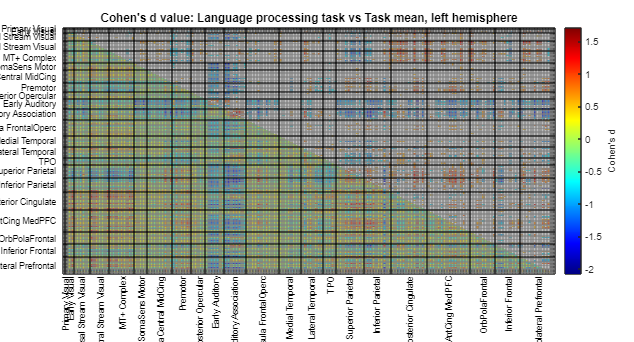

[pVal,~,Cohen_d]=perform_ttest2(Language_FC_L,Mean_FC_L); % performs paired t-tests for all matrix elements
rejection_BH_0001=benjamini_hochberg(pVal,0.001); % applies correction for multiple comparisons
Cohen_d_adj=adjust_Cohens_d(Cohen_d,rejection_BH_0001,10); % extracts highest Cohen's d
plot_Cohens_d(Cohen_d_adj,labelsregions,'Cohen''s d value: Language processing task vs Task mean, left hemisphere') % plots the graph

outputFilename = 'CD_language_vs_task_mean_L.jpg'; 
saveas(gcf, outputFilename, 'jpg');

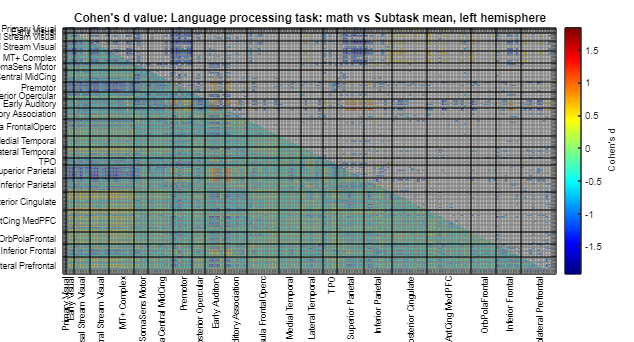

[pVal,~,Cohen_d]=perform_ttest2(Language_math_FC_L,Mean_FC_2_L);
rejection_BH_0001=benjamini_hochberg(pVal,0.001);
Cohen_d_adj=adjust_Cohens_d(Cohen_d,rejection_BH_0001,10);
plot_Cohens_d(Cohen_d_adj,labelsregions,'Cohen''s d value: Language processing task: math vs Subtask mean, left hemisphere')

outputFilename = 'CD_L_math_vs_subtask_mean_L.jpg'; 
saveas(gcf, outputFilename, 'jpg');

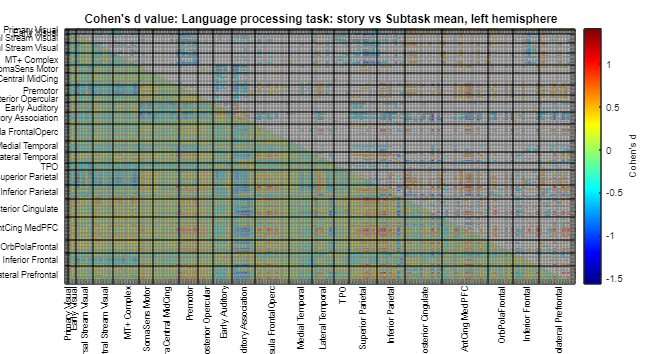

[pVal,~,Cohen_d]=perform_ttest2(Language_story_FC_L,Mean_FC_2_L);
rejection_BH_0001=benjamini_hochberg(pVal,0.001);
Cohen_d_adj=adjust_Cohens_d(Cohen_d,rejection_BH_0001,10);
plot_Cohens_d(Cohen_d_adj,labelsregions,'Cohen''s d value: Language processing task: story vs Subtask mean, left hemisphere')

outputFilename = 'CD_L_story_vs_subtask_mean_L.jpg'; 
saveas(gcf, outputFilename, 'jpg');